# Numerical Analysis Homework #7

## Problem #1: $y = \frac{1}{6}t^3e^t-te^t+2e^t-t-2$

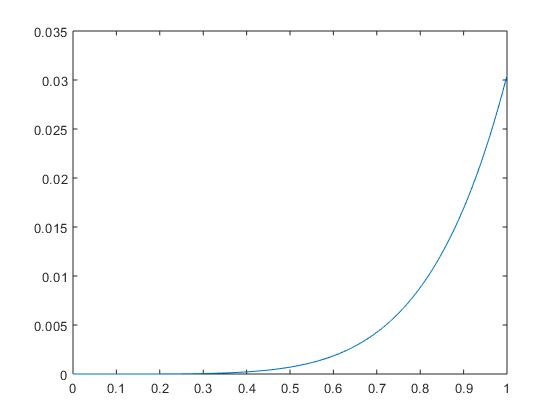

a = 0; b = 1; step = .01; y0 = 0;
F = @(t,r) (1/6).*exp(t).*t^3-t.*exp(t)+2.*exp(t)-t-2;
RungeKutta(step, [a,b], F ,y0);

## Problem #2: $y = e^{-t}+e^{2t}+e^{-2t}$

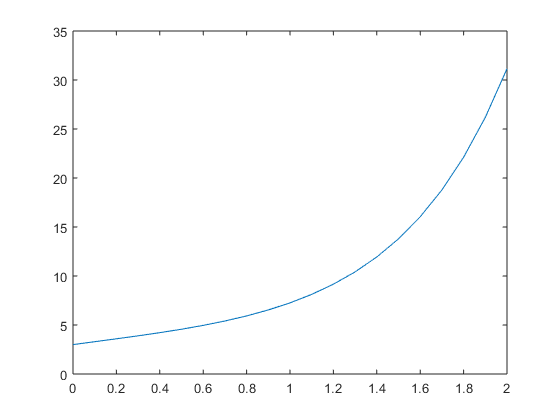

a = 0; b = 2; step = .1; y0 = 3;
F = @(t,r) exp(-t)+exp(2*t)+exp(-2*t);
RungeKutta(step, [a,b], F ,y0);

## Runge-Kutta 4th Order Function, referenced by above problems

function RungeKutta(h, range, F_xy , y1 )
x = range(1):h:range(2);
y = zeros(1,length(x)); 
y(1) = y1;

for i=1:(length(x)-1)
    k_1 = F_xy(x(i),y(i));
    k_2 = F_xy(x(i)+0.5*h,y(i)+0.5*h*k_1);
    k_3 = F_xy((x(i)+0.5*h),(y(i)+0.5*h*k_2));
    k_4 = F_xy((x(i)+h),(y(i)+k_3*h));

    y(i+1) = y(i) + (1/6)*(k_1+2*k_2+2*k_3+k_4)*h;
end

plot(x,y)
end